# Data exploration file

## Clean up variables and files

clear
close all
clc

## Reading data

Importing the data from the ABIDE dataset.

datapath = 'Data/FS_features_ABIDE_males.csv';
data = readtable(datapath)

data = 915×424 table
          FILE_ID          AGE_AT_SCAN    SEX     FIQ     DX_GROUP    lh_caudalanteriorcingulate_SurfArea    lh_caudalanteriorcingulate_GrayVol    lh_caudalanteriorcingulate_ThickAvg    lh_caudalanteriorcingulate_ThickStd    lh_caudalanteriorcingulate_MeanCurv    lh_caudalanteriorcingulate_CurvInd    lh_caudalmiddlefrontal_SurfArea    lh_caudalmiddlefrontal_GrayVol    lh_caudalmiddlefrontal_ThickAvg    lh_caudalmiddlefrontal_ThickStd    lh_caudalmiddlefrontal_MeanCurv    lh_caudalmiddlefrontal_CurvInd    lh_cuneus_SurfArea    lh_cuneus_GrayVol    lh_cuneus_ThickAvg    lh_cuneus_ThickStd    lh_cuneus_MeanCur

Let's show some information about the table.

data.Properties

ans =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {1×424 cell}
    VariableDescriptions: {1×424 cell}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


data.SEX = [];

The FILE_ID variable is interesting only for the site, so we can get rid of the info about the partifular subject.

data.FILE_ID = categorical(extractBefore(data.FILE_ID, "_00"));
data

data = 915×423 table
    FILE_ID    AGE_AT_SCAN     FIQ     DX_GROUP    lh_caudalanteriorcingulate_SurfArea    lh_caudalanteriorcingulate_GrayVol    lh_caudalanteriorcingulate_ThickAvg    lh_caudalanteriorcingulate_ThickStd    lh_caudalanteriorcingulate_MeanCurv    lh_caudalanteriorcingulate_CurvInd    lh_caudalmiddlefrontal_SurfArea    lh_caudalmiddlefrontal_GrayVol    lh_caudalmiddlefrontal_ThickAvg    lh_caudalmiddlefrontal_ThickStd    lh_caudalmiddlefrontal_MeanCurv    lh_caudalmiddlefrontal_CurvInd    lh_cuneus_SurfArea    lh_cuneus_GrayVol    lh_cuneus_ThickAvg    lh_cuneus_ThickStd    lh_cuneus_MeanCurv    lh_cuneus_Curv

It is also possible to make a summary of data content of the table.

summary(data)

Variables:

    FILE_ID: 915×1 categorical

        Properties:
            Description:  FILE_ID
        Values:

            CMU_a          13   
            CMU_b           8   
            Caltech        30   
            KKI            42   
            Leuven_1       28   
            Leuven_2       27   
            MaxMun_a       12   
            MaxMun_b        5   
            MaxMun_c       16   
            MaxMun_d       14   
            NYU           147   
            OHSU           28   
            Olin           31   
            Pitt           48   
            SBL            30   
            SDSU           28   
            Stanford       30   
            Trinity        49   
            UCLA_1         62   
            UCLA_2         23   
            UM_1           71   
            UM_2           32   
            USM           101   
            Yale           40   

    AGE_AT_SCAN: 915×1 double

        Properties:
       

Some fetures refers to left or right part of subjects brain; let's find out if they are in the same number.

lh_array = extractAfter(data.Properties.VariableNames, "lh_");
rh_array = extractAfter(data.Properties.VariableNames, "rh_");
numel(lh_array)

ans = 423

numel(rh_array)

ans = 423

## Box plot

In this section festures exploration will be performed through some box plot. First thing first it's possible to make a grid of box plots of variables for cases and control.

plotnumber = 9;
plotgridside = ceil(sqrt(plotnumber))

plotgridside = 3

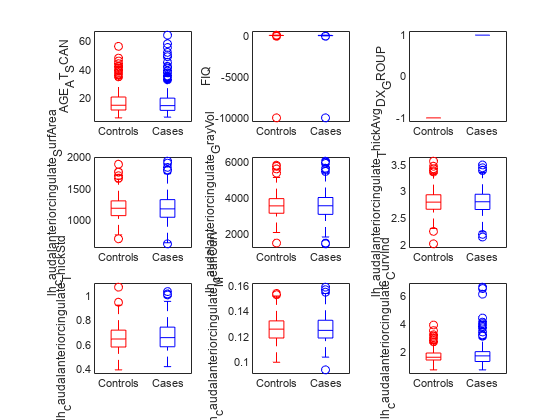

figure;
colors = 'rb';
for index = 1:plotnumber
    subplot(plotgridside, plotgridside, index)
    boxplot(data{:, data.Properties.VariableNames(index+1)}, ...
            data.DX_GROUP, 'colors', colors, 'symbol', 'o', 'Labels', {'Controls','Cases'});
    ylabel(data.Properties.VariableNames(index+1));
end

There is also the possibility of inspect a particula variable for each site, in this case AGE_AT_SCAN.

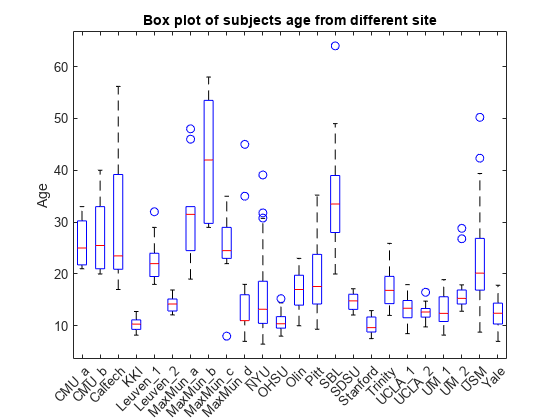

figure;
boxplot(data.AGE_AT_SCAN, data.FILE_ID, 'symbol', 'o');
title('Box plot of subjects age from different site')
ylabel('Age')

The same with another feature.

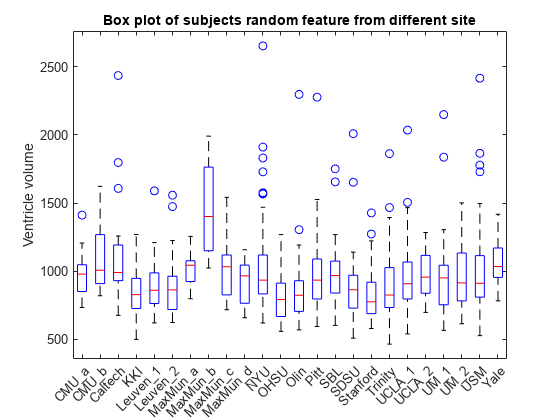

figure;
boxplot(data.x3rd_Ventricle_Volume_mm3, data.FILE_ID, 'symbol', 'o');
title('Box plot of subjects random feature from different site')
ylabel('Ventricle volume')

## Histograms

Histograms can be useful to show informaztion in a meaningful way. 

For example it's possible to make an histogram of fatures diveided for cases and controls, in order to highlight differences.

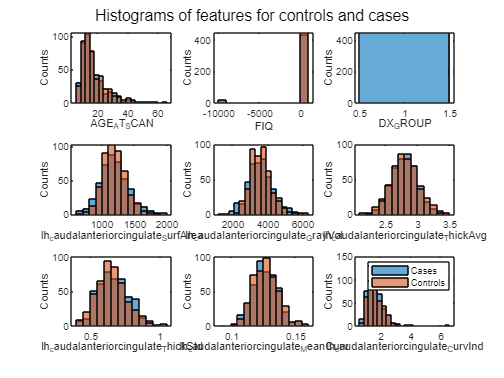

figure;
colors = 'rb';
for index = 1:plotnumber
    subplot(plotgridside, plotgridside, index)
    h=histogram(data{data.DX_GROUP==1, data.Properties.VariableNames(index+1)});
    xlabel(data.Properties.VariableNames(index+1));
    ylabel('Counts')
    hold on
    h=histogram(data{data.DX_GROUP==-1, data.Properties.VariableNames(index+1)}, h.BinEdges);
end
sgtitle('Histograms of features for controls and cases')
legend('Cases', 'Controls')

Another interesting apect to show is the representation by every site.

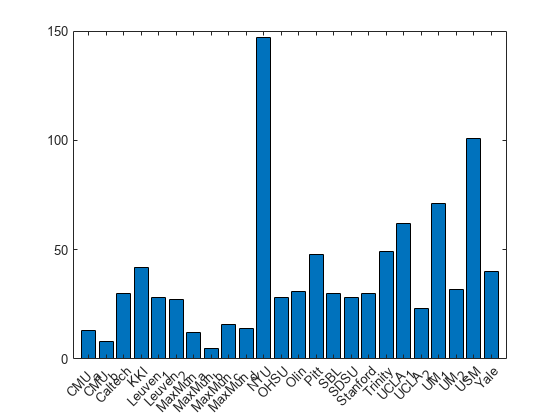

[site_names, ia, ic] = unique(data.FILE_ID);

site_counts = histcounts(ic)';
figure; bar(site_names, site_counts)

The same it's possible dividing controls and cases.

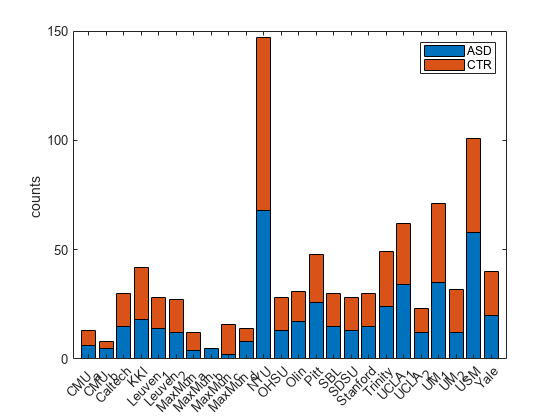

ic_cases = ic(data.DX_GROUP==1);
ic_controls = ic(data.DX_GROUP==-1);

site_counts_cases = histcounts(ic_cases)';
site_counts_controls = histcounts(ic_controls)';

figure; bar(site_names, [site_counts_cases site_counts_controls], 'stacked')
ylabel('counts ')
legend('ASD', 'CTR')

The difference in population origin can be a problem, because some kind of subjects can be more rrepresented than other.

For esample data form the NYU are much more than Calthech ones and they have heavly differnt subjects.

mean(data.AGE_AT_SCAN(data.FILE_ID=='NYU'))

ans = 15.0266

mean(data.AGE_AT_SCAN(data.FILE_ID=='Caltech'))

ans = 29.3800

## Outliers

Now it is the moment to eliminate outliers. A dumb implementation is to remove every outlier without discrimination.

This procedure will lead to a (too) much smaller dataset.

dataoutfree = rmoutliers(data(:,data.Properties.VariableNames(2:423)), 'mean')

dataoutfree = 373×422 table
    AGE_AT_SCAN    FIQ    DX_GROUP    lh_caudalanteriorcingulate_SurfArea    lh_caudalanteriorcingulate_GrayVol    lh_caudalanteriorcingulate_ThickAvg    lh_caudalanteriorcingulate_ThickStd    lh_caudalanteriorcingulate_MeanCurv    lh_caudalanteriorcingulate_CurvInd    lh_caudalmiddlefrontal_SurfArea    lh_caudalmiddlefrontal_GrayVol    lh_caudalmiddlefrontal_ThickAvg    lh_caudalmiddlefrontal_ThickStd    lh_caudalmiddlefrontal_MeanCurv    lh_caudalmiddlefrontal_CurvInd    lh_cuneus_SurfArea    lh_cuneus_GrayVol    lh_cuneus_ThickAvg    lh_cuneus_ThickStd    lh_cuneus_MeanCurv    lh_cuneus_CurvInd    

Let's visualize how situation changed with new box plots.

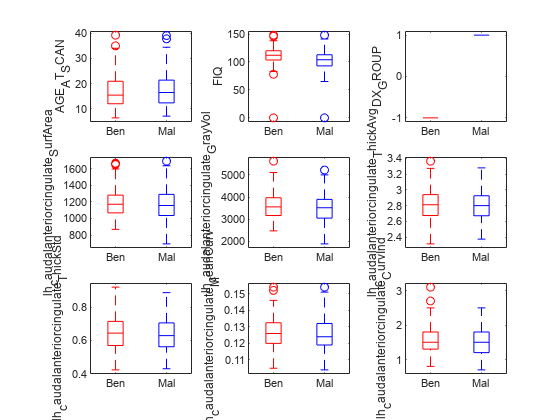

figure;
colors = 'rb';
for index = 1:plotnumber
    subplot(plotgridside, plotgridside, index)
    boxplot(dataoutfree{:, dataoutfree.Properties.VariableNames(index)}, ...
            dataoutfree.DX_GROUP, 'colors', colors, 'symbol', 'o', 'Labels', {'Ben','Mal'});
    ylabel(dataoutfree.Properties.VariableNames(index));
end

Hitsogram can be used to check if there are no more isolated values.

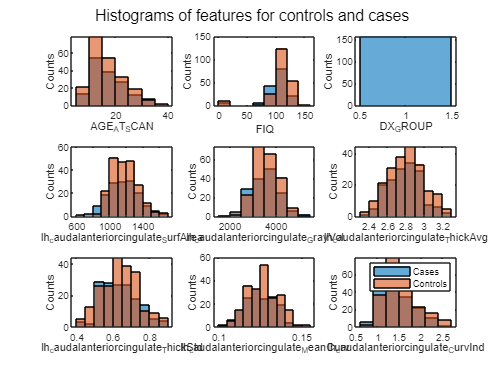

figure;
colors = 'rb';
for index = 1:plotnumber
    subplot(plotgridside, plotgridside, index)
    h=histogram(dataoutfree{dataoutfree.DX_GROUP==1, dataoutfree.Properties.VariableNames(index)});
    xlabel(dataoutfree.Properties.VariableNames(index));
    ylabel('Counts')
    hold on
    h=histogram(dataoutfree{dataoutfree.DX_GROUP==-1, dataoutfree.Properties.VariableNames(index)}, h.BinEdges);
end
sgtitle('Histograms of features for controls and cases')
legend('Cases', 'Controls')

## Statistical differences between controls and cases

It is important to check which variable are statistically different between controls and cases.

Before that lest'check if the variables are normally dictributed with a lilliefors test.

cases_data = table2array(dataoutfree(dataoutfree.DX_GROUP==1, dataoutfree.Properties.VariableNames(1:422)));
controls_data = table2array(dataoutfree(dataoutfree.DX_GROUP==-1, dataoutfree.Properties.VariableNames(1:422)));

p_cases = [];
h_cases = [];
for index = 1:size(dataoutfree, 2)
    [h, p] = lillietest(cases_data(:, index));
    p_cases = [p_cases, p];
    h_cases = [h_cases, h];
end

p_controls = [];
h_controls = [];
for index = 1:size(dataoutfree,2)
    [h, p] = lillietest(controls_data(:, index));
    p_controls = [p_controls, p];
    h_controls = [h_controls, h];
end

Let's se how many variables have significative results and so with the null hypotesis of normality rejected.

sum(h_cases)

ans = 129

sum(h_controls)

ans = 166

Now we can perform a two side non parametric Kolmogorov-Smirnov test in order to remark ariables whit differences between control and cases.

p_ks = [];
h_ks = [];
for index = 1:size(dataoutfree,2)
    [h, p] = kstest2(cases_data(:, index), controls_data(:, index));
    p_ks = [p_ks, p];
    h_ks = [h_ks, h];
end
dataoutfree.Properties.VariableNames(h_ks > 0.5)

ans = 1×14 cell array
    {'FIQ'}    {'DX_GROUP'}    {'lh_cuneus_SurfArea'}    {'lh_medialorbitofrontal_SurfArea'}    {'lh_rostralanteriorcingulate_GrayVol'}    {'rh_entorhinal_ThickStd'}    {'rh_inferiorparietal_GrayVol'}    {'rh_lingual_ThickStd'}    {'rh_middletemporal_ThickStd'}    {'rh_transversetemporal_MeanCurv'}    {'Left_Inf_Lat_Vent_Volume_mm3'}    {'x3rd_Ventricle_Volume_mm3'}    {'Left_Amygdala_Volume_mm3'}    {'CSF_Volume_mm3'}


Let's show a couple of the found variables.

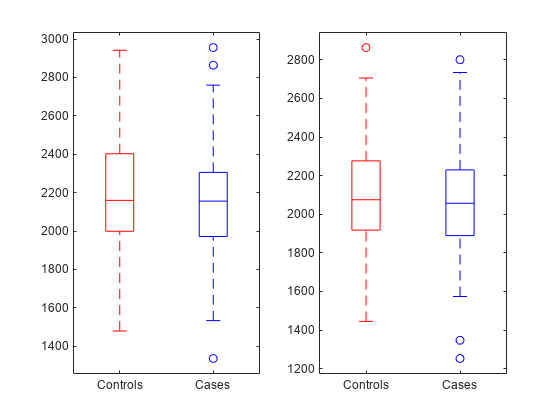

figure;
subplot(1, 2, 1)
h = boxplot(dataoutfree.lh_cuneus_SurfArea, dataoutfree.DX_GROUP, 'colors', colors, 'symbol', 'o', 'Labels', {'Controls', 'Cases'});
subplot(1, 2, 2)
h = boxplot(dataoutfree.rh_cuneus_SurfArea, dataoutfree.DX_GROUP, 'colors', colors, 'symbol', 'o', 'Labels', {'Controls', 'Cases'});

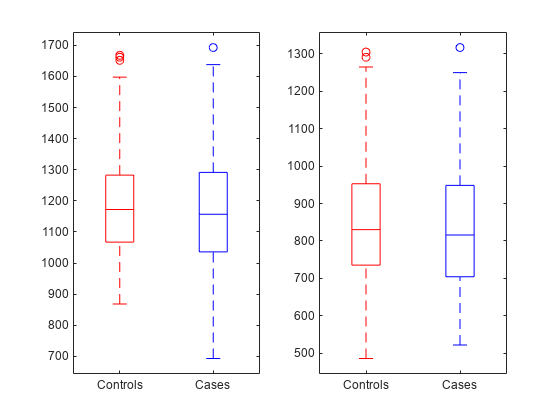

figure;
subplot(1, 2, 1)
h = boxplot(dataoutfree.lh_caudalanteriorcingulate_SurfArea, dataoutfree.DX_GROUP, 'colors', colors, 'symbol', 'o', 'Labels', {'Controls', 'Cases'});
subplot(1, 2, 2)
h = boxplot(dataoutfree.rh_caudalanteriorcingulate_SurfArea, dataoutfree.DX_GROUP, 'colors', colors, 'symbol', 'o', 'Labels', {'Controls', 'Cases'});

## Correlation study

Now it's the turn of correlation between features and labesl.

correlation = [];
for index = 1:size(dataoutfree, 2)
    rho = corr(dataoutfree.DX_GROUP, dataoutfree{:, dataoutfree.Properties.VariableNames(index)});
    correlation = [correlation, rho];
end

correlation

correlation =     0.0437   -0.1085    1.0000   -0.0548   -0.0650   -0.0320   -0.0247   -0.0734   -0.0802   -0.1100   -0.0724    0.0654   -0.0058   -0.0237   -0.0549   -0.0800   -0.0398    0.0379    0.0313    0.0065   -0.0559   -0.0311   -0.0054    0.0397    0.0307    0.0014   -0.0167   -0.0643   -0.0582   -0.0087    0.0406    0.0639    0.0089   -0.0786   -0.0563    0.0176    0.0264    0.0247   -0.0060   -0.0299    0.0077    0.0413    0.0420    0.0097   -0.0401    0.0410    0.0185   -0.0239    0.0628   -0.1164


Only the most correlated features are taken in count.

dataoutfree.Properties.VariableNames(abs(correlation) > 0.1)

ans = 1×13 cell array
    {'FIQ'}    {'DX_GROUP'}    {'lh_caudalmiddlefrontal_SurfArea'}    {'lh_isthmuscingulate_MeanCurv'}    {'lh_lateraloccipital_ThickAvg'}    {'rh_entorhinal_ThickStd'}    {'rh_lateraloccipital_ThickAvg'}    {'rh_lingual_ThickStd'}    {'rh_middletemporal_ThickStd'}    {'Left_Inf_Lat_Vent_Volume_mm3'}    {'x3rd_Ventricle_Volume_mm3'}    {'Left_Amygdala_Volume_mm3'}    {'CSF_Volume_mm3'}


Let's see how many variables are in common between the most correlated with labels and with different distribution.

intersect(dataoutfree.Properties.VariableNames(abs(correlation) > 0.1), dataoutfree.Properties.VariableNames(h_ks > 0.5))

ans = 1×9 cell array
    {'CSF_Volume_mm3'}    {'DX_GROUP'}    {'FIQ'}    {'Left_Amygdala_Volume_mm3'}    {'Left_Inf_Lat_Vent_Volume_mm3'}    {'rh_entorhinal_ThickStd'}    {'rh_lingual_ThickStd'}    {'rh_middletemporal_ThickStd'}    {'x3rd_Ventricle_Volume_mm3'}


It is possible to check for variables that are found correlated against the null hypotesis of no correlation.

[corr_matrix, p_matrix] = corr(dataoutfree{:,:}, dataoutfree{:,:});
dataoutfree.Properties.VariableNames(p_matrix(3, :) < 0.05)

ans = 1×13 cell array
    {'FIQ'}    {'DX_GROUP'}    {'lh_caudalmiddlefrontal_SurfArea'}    {'lh_isthmuscingulate_MeanCurv'}    {'lh_lateraloccipital_ThickAvg'}    {'rh_entorhinal_ThickStd'}    {'rh_lateraloccipital_ThickAvg'}    {'rh_lingual_ThickStd'}    {'rh_middletemporal_ThickStd'}    {'Left_Inf_Lat_Vent_Volume_mm3'}    {'x3rd_Ventricle_Volume_mm3'}    {'Left_Amygdala_Volume_mm3'}    {'CSF_Volume_mm3'}


Again check for variables in common.

intersect(dataoutfree.Properties.VariableNames(p_matrix(3,:) < 0.05), dataoutfree.Properties.VariableNames(h_ks > 0.5))

ans = 1×9 cell array
    {'CSF_Volume_mm3'}    {'DX_GROUP'}    {'FIQ'}    {'Left_Amygdala_Volume_mm3'}    {'Left_Inf_Lat_Vent_Volume_mm3'}    {'rh_entorhinal_ThickStd'}    {'rh_lingual_ThickStd'}    {'rh_middletemporal_ThickStd'}    {'x3rd_Ventricle_Volume_mm3'}


intersect(dataoutfree.Properties.VariableNames(p_matrix(3,:) < 0.05), dataoutfree.Properties.VariableNames(abs(correlation) > 0.1))

ans = 1×13 cell array
    {'CSF_Volume_mm3'}    {'DX_GROUP'}    {'FIQ'}    {'Left_Amygdala_Volume_mm3'}    {'Left_Inf_Lat_Vent_Volume_mm3'}    {'lh_caudalmiddlefrontal_SurfArea'}    {'lh_isthmuscingulate_MeanCurv'}    {'lh_lateraloccipital_ThickAvg'}    {'rh_entorhinal_ThickStd'}    {'rh_lateraloccipital_ThickAvg'}    {'rh_lingual_ThickStd'}    {'rh_middletemporal_ThickStd'}    {'x3rd_Ventricle_Volume_mm3'}


## Features selection

In this part variables selection will be performed using methods presented in the previous section.

First eliminate DX_GROUP for now (it is not a feature to filter).

newdata = dataoutfree;
newdata.DX_GROUP = []

newdata = 373×421 table
    AGE_AT_SCAN    FIQ    lh_caudalanteriorcingulate_SurfArea    lh_caudalanteriorcingulate_GrayVol    lh_caudalanteriorcingulate_ThickAvg    lh_caudalanteriorcingulate_ThickStd    lh_caudalanteriorcingulate_MeanCurv    lh_caudalanteriorcingulate_CurvInd    lh_caudalmiddlefrontal_SurfArea    lh_caudalmiddlefrontal_GrayVol    lh_caudalmiddlefrontal_ThickAvg    lh_caudalmiddlefrontal_ThickStd    lh_caudalmiddlefrontal_MeanCurv    lh_caudalmiddlefrontal_CurvInd    lh_cuneus_SurfArea    lh_cuneus_GrayVol    lh_cuneus_ThickAvg    lh_cuneus_ThickStd    lh_cuneus_MeanCurv    lh_cuneus_CurvInd    lh_entorhinal_SurfArea 

Redo the same analysis shown before.

[new_corr_matrix, new_p_matrix] = corr(newdata{:,:}, newdata{:,:});
new_corr_matrix

new_corr_matrix =     1.0000    0.1018    0.1134   -0.0850   -0.4236   -0.2413    0.0034   -0.0595    0.0507   -0.1921   -0.4101   -0.3191   -0.1167    0.0673    0.0207   -0.2847   -0.5274   -0.4678   -0.2793   -0.0235    0.0649    0.0989    0.0627    0.0882   -0.1002   -0.0070    0.0437   -0.1189   -0.3035   -0.0955   -0.0705   -0.0328   -0.0584   -0.4192   -0.6285   -0.4463   -0.0859   -0.1320    0.1214   -0.0781   -0.2655   -0.1789   -0.0642   -0.0188   -0.0527   -0.2906   -0.2851   -0.3849    0.0273   -0.0227
    0.1018    1.0000    0.0304   -0.0722   -0.1406   -0.0401    0.1693    0.1454    0.0291    0.0588    0.1699   -0.2287   -0.0555    0.1278    0.0242   -0.0463   -0.1435   -0.1353   -0.1510    0.1414    0.1268    0.0884   -0.0871    0.0885    0.0464    0.1044    0.0576   -0.0064   -0.1581    0.0796    0.1246    0.1943    0.0166   -0.0793   -0.0722   -0.2492   -0.0839    0.0490    0.0335   -0.0160   -0.0465   -0.0211   -0.0461    0.1096    0.0379   -0.0293   -0.1161   -0.1000 

new_p_matrix

new_p_matrix =          0    0.0494    0.0286    0.1011    0.0000    0.0000    0.9474    0.2520    0.3289    0.0002    0.0000    0.0000    0.0242    0.1947    0.6901    0.0000    0.0000    0.0000    0.0000    0.6509    0.2112    0.0563    0.2272    0.0889    0.0532    0.8932    0.4003    0.0216    0.0000    0.0653    0.1740    0.5272    0.2602    0.0000    0.0000    0.0000    0.0978    0.0107    0.0190    0.1322    0.0000    0.0005    0.2163    0.7171    0.3097    0.0000    0.0000    0.0000    0.5989    0.6619
    0.0494         0    0.5584    0.1643    0.0065    0.4401    0.0010    0.0049    0.5758    0.2575    0.0010    0.0000    0.2853    0.0135    0.6410    0.3724    0.0055    0.0089    0.0035    0.0062    0.0143    0.0883    0.0930    0.0877    0.3712    0.0440    0.2670    0.9013    0.0022    0.1251    0.0161    0.0002    0.7488    0.1263    0.1641    0.0000    0.1055    0.3450    0.5191    0.7581    0.3701    0.6840    0.3748    0.0344    0.4657    0.5728    0.0249    0.0536    

results = [];
for index = 1:size(newdata, 2)
    corr_number = sum(new_p_matrix(index, :) < 0.05);
    results = [results, corr_number];
end
results

results =    269   137   266   235   228   172    74   254   201   261   229   227   175   255   173   216   222   278   198   212   196   225   197    72   194   132   244   233   260   228   295   258   203   274   234   246   257   265   262   247   251   238   265   254   222   264   196   213   202   272


Here most correlated fatures with the other are eliminated.

for index = 1:372
    [maximum, position] = max(results);
    newdata(:, position) = [];
    [for_corr_matrix, for_p_matrix] = corr(newdata{:,:}, newdata{:,:});
    results = [];
    for i = 1:size(newdata, 2)
        corr_number = sum(for_p_matrix(i, :) < 0.05);
        results = [results, corr_number];
    end
end
results

results =      7     7     8    10     9     5    10     6     7     8     5     8     8     7    10    11    10    10     5    10     8    10     9     5     7     6    10    11     7     9    10    10    10     8     8    12    10    12     6     4    11     8     7     3     9     3    10    11    10


Check the survived variables after the study of correlation.

newdata.Properties.VariableNames

ans = 1×49 cell array
    {'FIQ'}    {'lh_caudalanteriorcingulate_ThickStd'}    {'lh_caudalanteriorcingulate_MeanCurv'}    {'lh_caudalmiddlefrontal_SurfArea'}    {'lh_cuneus_SurfArea'}    {'lh_entorhinal_ThickStd'}    {'lh_lateraloccipital_SurfArea'}    {'lh_lingual_ThickStd'}    {'lh_medialorbitofrontal_ThickStd'}    {'lh_medialorbitofrontal_MeanCurv'}    {'lh_parahippocampal_MeanCurv'}    {'lh_parahippocampal_CurvInd'}    {'lh_parsopercularis_SurfArea'}    {'lh_parstriangularis_SurfArea'}    {'lh_parstriangularis_MeanCurv'}    {'lh_pericalcarine_GrayVol'}    {'lh_pericalcarine_CurvInd'}    {'lh_posteriorcingulate_MeanCurv'}    {'lh_rostralanteriorcingulate_MeanCurv'}    {'rh_caudalanteriorcingulate_ThickStd'}    {'rh_caudalanteriorcingulate_MeanCurv'}    {'rh_caudalanteriorcingulate_CurvInd'}    {'rh_cuneus_MeanCurv'}    {'rh_entorhinal_ThickStd'}    {'rh_lingual_ThickStd'}    {'rh_medialorbitofrontal_ThickStd'}    {'rh_parahippocampal_ThickStd'}    {'rh_parahippocampal_CurvInd'}    

In order to reduce even more the features, only data with two interesting properties are kept (in the folow index 3 of p_matrix is liked to DX_GROUP in data).

first_list = intersect(dataoutfree.Properties.VariableNames(p_matrix(3, :) < 0.05), newdata.Properties.VariableNames)

first_list = 1×5 cell array
    {'FIQ'}    {'lh_caudalmiddlefrontal_SurfArea'}    {'rh_entorhinal_ThickStd'}    {'rh_lingual_ThickStd'}    {'x3rd_Ventricle_Volume_mm3'}


second_list = intersect(dataoutfree.Properties.VariableNames(h_ks > 0.5), newdata.Properties.VariableNames)

second_list = 1×5 cell array
    {'FIQ'}    {'lh_cuneus_SurfArea'}    {'rh_entorhinal_ThickStd'}    {'rh_lingual_ThickStd'}    {'x3rd_Ventricle_Volume_mm3'}


third_list = intersect(dataoutfree.Properties.VariableNames(p_matrix(3,:) < 0.05), dataoutfree.Properties.VariableNames(h_ks > 0.5))

third_list = 1×9 cell array
    {'CSF_Volume_mm3'}    {'DX_GROUP'}    {'FIQ'}    {'Left_Amygdala_Volume_mm3'}    {'Left_Inf_Lat_Vent_Volume_mm3'}    {'rh_entorhinal_ThickStd'}    {'rh_lingual_ThickStd'}    {'rh_middletemporal_ThickStd'}    {'x3rd_Ventricle_Volume_mm3'}


variables_of_interest = union(first_list, second_list)

variables_of_interest = 1×6 cell array
    {'FIQ'}    {'lh_caudalmiddlefrontal_SurfArea'}    {'lh_cuneus_SurfArea'}    {'rh_entorhinal_ThickStd'}    {'rh_lingual_ThickStd'}    {'x3rd_Ventricle_Volume_mm3'}


variables_of_interest = union(variables_of_interest, third_list)

variables_of_interest = 1×11 cell array
    {'CSF_Volume_mm3'}    {'DX_GROUP'}    {'FIQ'}    {'Left_Amygdala_Volume_mm3'}    {'Left_Inf_Lat_Vent_Volume_mm3'}    {'lh_caudalmiddlefrontal_SurfArea'}    {'lh_cuneus_SurfArea'}    {'rh_entorhinal_ThickStd'}    {'rh_lingual_ThickStd'}    {'rh_middletemporal_ThickStd'}    {'x3rd_Ventricle_Volume_mm3'}


## Saving manipulated data

newdata = dataoutfree(:, variables_of_interest);
newdata.AGE_AT_SCAN = dataoutfree.AGE_AT_SCAN;
newdata.DX_GROUP = [];
newdata.DX_GROUP = dataoutfree.DX_GROUP;
newdata

newdata = 373×12 table
    CSF_Volume_mm3    FIQ    Left_Amygdala_Volume_mm3    Left_Inf_Lat_Vent_Volume_mm3    lh_caudalmiddlefrontal_SurfArea    lh_cuneus_SurfArea    rh_entorhinal_ThickStd    rh_lingual_ThickStd    rh_middletemporal_ThickStd    x3rd_Ventricle_Volume_mm3    AGE_AT_SCAN    DX_GROUP
    ______________    ___    ________________________    ____________________________    _______________________________    __________________    ______________________    ___________________    __________________________    _________________________    ___________    ________

        1537

writetable(newdata, 'Data/ABIDE_modified_dataset.xlsx');